
y = getaudiodata(recObj);
filename = 'exp5_prob3.wav'

filename = 'exp5_prob3.wav'

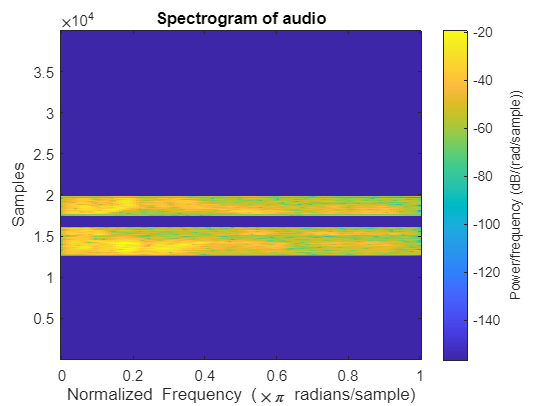

audiowrite(filename,y,fs)
w = hanning(100);
spectrogram(y,w)
title('Spectrogram of audio')

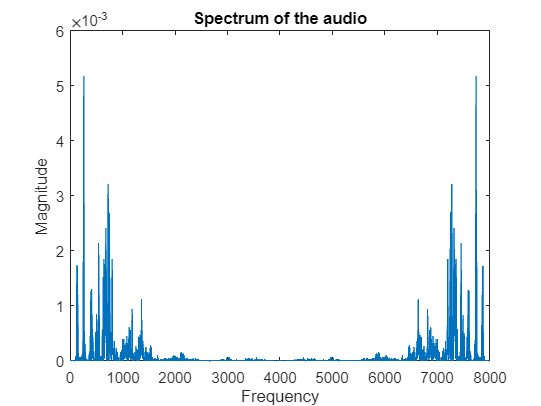

f = fft(y);
n = length(y);
fs = 8000;
l = (0:n-1)*(fs/n);     
p = abs(f).^2/n;    
plot(l,p)
title('Spectrum of the audio')
xlabel('Frequency')
ylabel('Magnitude')